# MPC-SensorlessAO MATLAB Code

## Sensorless adaptive optics system overview

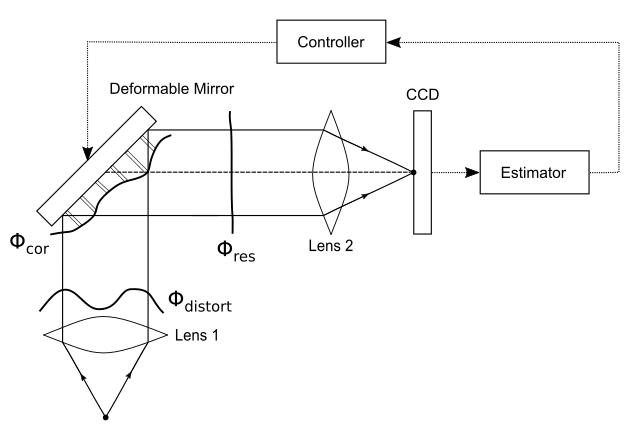

## Generating time-varying phase aberrations by OOMAO Toolbox

The time-varying phase aberration caused by atmospheric turbulence is generated by **Object-Oriented MATLAB & Adaptive Optics (OOMAO) Toolbox** [[2]].

The OOMAO sources are hosted by GitHub (https://github.com/rconan/OOMAO).

To illustrate a complex environment such as the real-world atmosphere, we designed a *mainly frozen-flow model* with three layers at diferent heights, wind speeds, and directions [[3]].

clear;clc;close all;

 @(logBook)> Closing the log book!
~~~~~~~~~~~~~~~~~~~
 OOMAO'S GONE!
~~~~~~~~~~~~~~~~~~~


addpath(genpath('.\OOMAO-master'))


samplingFreq = 200; % turbulence sampling frequency
nSimSteps = 2000; % total number of phase screen
nPolynomials = 28; % number of zernike modes (radial number = 6)

D = 1; % telescope diameter [m]
r0 = 0.2; % Fried parameter [m] % The strength of atmospheric turbulence (D/r0) is set as 5.
L0 = 42; % outer scale [m]

% mainly frozen-flow model
h = [1000, 5000, 12000]; % height [m]
v0 = [5, 7.5, 10]; % wind speed [m/s]
vD = [0, pi/3, 5*pi/3];

f_r0 = [0.7, 0.1, 0.2]./25; % Fractional r0

atm = atmosphere(photometry.V,r0,L0,'fractionnalR0',f_r0,'altitude',h,'windSpeed',v0,'windDirection',vD); % atmosphere

~~~~~~~~~~~~~~~~~~~
 BEWARE OF OOMAO!
~~~~~~~~~~~~~~~~~~~
 @(logBook)> Opening the log book!
___ ATMOSPHERE ___
 Von Karman atmospheric turbulence
  . wavelength  =  0.55micron,
  . r0          = 20.00cm,
  . L0          = 42.00m,
  . seeing      =  0.56arcsec,
  . theta0(37%) = 43.04arcsec,
  . tau0(37%)   = 142.17millisec
----------------------------------------------------
  Layer   Altitude[m]   fr0    wind([m/s] [deg])   D[m]    res[px]
   1       1000.00      0.03    ( 5.00   0.00)                 
   2       5000.00      0.00    ( 7.50  60.00)                 
   3      12000.00      0.01    (10.00 300.00)                 
----------------------------------------------------



% telescope setting
nL = 512; % number of lenslet
nPx = 1; % number or pixel per lenslet
nRes = nL*nPx; % resolution
xaxis = 1:nRes;
d = D/nL; % lenslet pitch

tel = telescope(D,'resolution',nRes,'fieldOfViewInArcsec',2.5,'samplingTime',1/samplingFreq); % telescope

     []

___ TELESCOPE ___
 1.00m diameter full aperture with  0.79m^2 of light collecting area;
 the field-of-view is 0.04arcmin; the pupil is sampled with 512X512 pixels
----------------------------------------------------


tel = tel + atm;

   Layer 1:
            -> Computing initial phase screen (D=1.01m,n=518px) ...  Done 
            -> # of elements for the outer maks: 2076 and for the inner mask 4128
            -> Computing matrix A and B for layer 1: ZZt , ZXt , XXt ...  Done 
   Layer 2:
            -> Computing initial phase screen (D=1.06m,n=543px) ...  Done 
            -> # of elements for the outer maks: 2176 and for the inner mask 4328
            -> Computing matrix A and B for layer 2: ZZt , ZXt , XXt ...  Done 
   Layer 3:
            -> Computing initial phase screen (D=1.15m,n=586px) ...  Done 
            -> # of elements for the outer maks: 2348 and for the inner mask 4672
            -> Computing matrix A and B for layer 3: ZZt , ZXt , XXt ...  Done 



% Photometric system
% Band ( wavelength , bandwidth , zero point )
% V  ( 0.550e-6 , 0.090e-6 , 3.3e12 )
ngs = source('wavelength',photometry.V); % natural guide star

___ SOURCE ___
 Obj   zen[arcsec] azim[deg]  height[m]  lambda[micron] magnitude
  1      0.00        0.00         Inf     0.550           0.00
----------------------------------------------------


ngs = ngs.*tel;

sprintf('Calculating wavefront for %d steps ...',nSimSteps);

phase = []; time_phase = [];
for iSimStep=1:nSimSteps
    +ngs;
    +tel;
    phase(:,:,iSimStep) = ngs.meanRmPhase; % time-varying phase aberrations (mainly frozen-flow model)
    time_phase(iSimStep) = ngs.timeStamp;
end

경과 시간은 0.988813초입니다.
경과 시간은 0.999914초입니다.
경과 시간은 0.921106초입니다.
경과 시간은 0.959962초입니다.
경과 시간은 0.924726초입니다.
경과 시간은 0.928202초입니다.
경과 시간은 0.914256초입니다.
경과 시간은 0.921358초입니다.
경과 시간은 0.926330초입니다.
경과 시간은 0.915388초입니다.
경과 시간은 0.924911초입니다.
경과 시간은 0.900464초입니다.
경과 시간은 0.914810초입니다.
경과 시간은 0.936549초입니다.
경과 시간은 0.913829초입니다.
경과 시간은 0.962434초입니다.
경과 시간은 0.929119초입니다.
경과 시간은 0.904106초입니다.
경과 시간은 0.910554초입니다.
경과 시간은 0.957560초입니다.
경과 시간은 0.946668초입니다.
경과 시간은 0.989511초입니다.
경과 시간은 0.990678초입니다.
경과 시간은 0.983875초입니다.
경과 시간은 0.965849초입니다.
경과 시간은 0.958045초입니다.
경과 시간은 0.901114초입니다.
경과 시간은 0.923203초입니다.
경과 시간은 0.932489초입니다.
경과 시간은 0.934124초입니다.
경과 시간은 0.945028초입니다.
경과 시간은 0.909046초입니다.
경과 시간은 0.977389초입니다.
경과 시간은 0.944443초입니다.
경과 시간은 0.919247초입니다.
경과 시간은 0.977101초입니다.
경과 시간은 0.940757초입니다.
경과 시간은 0.932154초입니다.
경과 시간은 0.985725초입니다.
경과 시간은 0.943003초입니다.
경과 시간은 0.912589초입니다.
경과 시간은 0.942861초입니다.
경과 시간은 0.982403초입니다.
경과 시간은 0.917342초입니다.
경과 시간은 0.919825초입니다.
경과 시간은 0.941051초입니다.
경과 시간은 0.919505초입니다.
경과 시간은 0.9156


% Fitting the Zernike coefficients constituting the time-varying phase aberrations
x = (-(nL-1):2:(nL-1))/(nL-1);
[X,Y] = meshgrid(x);
[theta,r] = cart2pol(X,Y);    % convert to polar coordinate
is_in = r <= max(abs(x));

r = r(is_in);
theta = theta(is_in);

N = 6; % order of zernike mode
nx = (N+1)*(N+2)/2; % number of states

ad_acc = []; 
for j=1:size(phase,3)
    z = squeeze(phase(:,:,j)); % Unit : [rad]
    [ad_new,nm_new] = zernmodfit(r,theta,z(is_in),N); % Modified Zernike Decomposition
    ad_acc = [ad_acc; ad_new(:,1)']; % Zernike coefficients constituting the time-varying phase
end



## Model Identification based on Time-series method

num_data = size(ad_acc,1);

ad_acc(:,1) = []; % piston element is removed

num_train = 1000; % number of training set
num_valid = 500; % number of validation set
num_test = 500; % number of test set

PN = 2; % order of VAR model
AA = []; % model of training set
BB = [];

for i=PN+1:num_train
    for j=1:PN
        AA(i-PN,size(ad_acc,2)*(j-1)+1:size(ad_acc,2)*j) = ad_acc(i-j,:);
    end
    BB(i-PN,:) = ad_acc(i,:);
end

PARA = (AA'*AA)\AA'*BB;

A1 = PARA(1:size(ad_acc,2),:);
A2 = PARA(1+size(ad_acc,2):2*size(ad_acc,2),:);

BB_ts_train = AA*PARA;

% validation set
AA_valid = []; % model of validation set
BB_valid = [];
for i=1:num_test
    for j=1:PN
        AA_valid(i,size(ad_acc,2)*(j-1)+1:size(ad_acc,2)*j) = ad_acc(i+num_train-j,:);
    end
    BB_valid(i,:) = ad_acc(i+num_train,:);
end

BB_ts_valid = AA_valid*PARA;


ad_diff_test = BB_ts_valid - BB_valid;

RMSE_valid = []; RRMSE_valid = [];
for j=1:size(ad_acc,2)
    RMSE_valid = [RMSE_valid; sqrt(mean((BB_ts_valid(:,j) - BB_valid(:,j)).^2))];
    RRMSE_valid = [RRMSE_valid; RMSE_valid(j,1)/(max(BB_valid(:,j)) - min(BB_valid(:,j)))];
end

RMSE_valid = [0; RMSE_valid]; RRMSE_valid = [0; RRMSE_valid];

% Compare the zernike coefficients of validation set between original and generation via PARA
BB_valid = [zeros(size(BB_valid,1),1) BB_valid];
BB_ts_valid = [zeros(size(BB_ts_valid,1),1) BB_ts_valid];

BB_valid = [zeros(num_train,size(BB_valid,2)); BB_valid];
BB_ts_valid = [zeros(num_train,size(BB_ts_valid,2)); BB_ts_valid];

for i=1:size(ad_acc,2)
    j = i;
    figure(15)
    subplot(4,7,i)
    hold on
    plot(BB_ts_valid(:,j),'b-','LineWidth',1.5)
    plot(BB_valid(:,j),'r--','LineWidth',1.5)
    hold off
    axis square
    title(['\alpha_{k}(' num2str(j) ')'])
    xlabel('Time index, k')
    xlim([(num_train + 1) (num_train + num_test)])
    ylim([-2 2])
    set(gca,'FontSize',15)
end
legend('Predicted','Actual')

## The influence matrix of Deformable Mirror (DM) generation

dx = 6.5e-6; %0.1e-6;   % pixel spacing (m)

coupling = 0.1; % coupling parameter, defining the width of functions [0.05 ~ 0.15]
D = 4.4e-3; % telescope diameter, [m]
m1 = 12; % number of actuator array, m = (m1)^2
m = m1^2; % total number of actuators

n = 6; % order of zernike mode -> total 28 modes
nx = (n+1)*(n+2)/2;

d = D/(m1-1); % distance between actuators in pupil plane

len_dm = round((2.2e-3)*2/dx);
xaxis_dm = ((-len_dm/2):(len_dm/2-1))*dx;
yaxis_dm = -xaxis_dm;

[XX_dm,YY_dm] = meshgrid(xaxis_dm,yaxis_dm);  %2-D arrays hold x location and fy location of all points

diff_dm_idx = floor(len_dm/(m1-1));
x0_dm_idx = 1;
for i=1:(m1-1)
    x0_dm_idx = [x0_dm_idx; 1+i*diff_dm_idx];
end
x0_dm_idx(end) = len_dm;

x0_dm_axis = xaxis_dm(x0_dm_idx)';
y0_dm_axis = yaxis_dm(x0_dm_idx)';

act_idx = 0;
B_dm = zeros(len_dm,len_dm,m);
for i=1:m1
    for j=1:m1
        x_diff = XX_dm - x0_dm_axis(j);
        y_diff = YY_dm - y0_dm_axis(i);
        act_idx = act_idx + 1;
        
        B_g = 0 + 1*exp( log(coupling)*( ((x_diff).^2 + (y_diff).^2 )/(d^2) ) );
        
        B_dm(:,:,act_idx) = B_g;
    end
end

% pupil plane
len = 512; % number of pixels in the array
cen = len/2 + 1;
df = 1/(len*dx); % spacing in the spatial frequency domain (cycles/m)

xaxis = ((-len/2):(len/2-1))*dx;
yaxis = -xaxis;

[XX,YY] = meshgrid(xaxis,yaxis);  %2-D arrays hold x location and fy location of all points

N = len-1;
x = (-N:2:N)/N;
[X,Y] = meshgrid(x);
[theta,r] = cart2pol(X,Y);    % convert to polar coordinate
is_in = r <= max(abs(x));
% z(~is_in) = nan;
r = r(is_in);
theta = theta(is_in);

[t1,max_idx] = min(abs(xaxis_dm - xaxis(end)));
[t2,min_idx] = min(abs(xaxis_dm - xaxis(1)));

B_pupil = zeros(len,len,m); B_pupil_isin = zeros(size(r,1),m);
for t=1:size(B_dm,3)
    B_pupil(:,:,t) = B_dm(min_idx:max_idx,min_idx:max_idx,t);
    temp = B_pupil(:,:,t);
    B_pupil_isin(:,t) = temp(is_in);
end

% Fitted by Zernike polynomials
load("./Zs.mat") % load Zernike polynomials

Zs_new = reshape(Zs,size(Zs,1),len^2)'; 
B_pupil_new = reshape(B_pupil,len^2,size(B_pupil,3));

B = pinv(Zs_new'*Zs_new)*Zs_new'*B_pupil_new; % Influence matrix

## Model Predictive Control Simulation

### Setup the simulation parameters

load("./model_approx.mat") % load first-order approximation model
load("./SNR_10.mat") % load measurement noise (SNR = 10 [dB])

 @(logBook)> Closing the log book!
~~~~~~~~~~~~~~~~~~~
 OOMAO'S GONE!
~~~~~~~~~~~~~~~~~~~


다음 사용 중 오류가 발생함: load
'./input_data/new/input_data_3layer_mainly_frozen_v2.mat'을(를) 현재 폴더 또는 MATLAB 경로에서 찾을 수 없지만 다음 위치에 있습니다.
 D:\Users\Her\Documents\MATLAB\AO\4F-Optical-Correlator-Simulation-kim\mpc

MATLAB 현재 폴더를 변경하십시오 또는 해당 폴더를 MATLAB 경로에 추가하십시오.

sample = 1;

mag_conv_5 = 1;
mag_conv_10 = 1.781797436291855;
mag_conv_15 = 2.498049532979032;
mag_conv_20 = 3.174802103932926;

phase = phase .* mag_conv_10;
ad_acc = ad_acc .* mag_conv_10;

% A = A'; % VAR(1) model
A1 = A1'; % input_data에 저장된 A가 x*A 형태로 쓰였기 때문에 변환 필요
A2 = A2';

% piston element is removed
B(1,:) = []; A_s(:,1) = [];

nx = size(A1,1); % number of state
nu = size(B,2); % number of input
p = size(A_s,1); % number of measurements   

n_mode = 6; % number of zernike modes
N = 2; % prediction horizon for MPC
T_final = 500; % size(phase,3) - num_train - num_test;
T_settle = 1.0e-3;
T_s = 0.1e-3; % sampling time of MPC Simulation
T_s_tur = 5e-3;

%% J = U'*H*U + r'*U + c
Q = (1.5e+4)*eye(nx,nx); % weighting matrix for error state
P = (1e+0)*Q; % weighting matrix for terminal error 
R = (1e+0)*eye(nu,nu);% weighting matrix for cost function

% SNR = 10; % the magnitude of desired SNR [db]

coeff_a = 0.047275; coeff_b = 2.709264; coeff_c = 0; % Unit change parameters (Voltage to Deflection)

u_min = -28*ones(nu,1); % input box constraint [rad]
u_max = 28*ones(nu,1);  % 28 [rad] -> 200 [V]

du_min = -0.2121*ones(nu,1); % ramp-rate constraint [rad]
du_max = 0.2121*ones(nu,1);

U_min = repmat(u_min,N,1);
U_max = repmat(u_max,N,1);

dU_min = repmat(du_min,N,1);
dU_max = repmat(du_max,N,1);


#### Make pixel array for image plane and pupil plane

% y_ref generation by FFT2
len = 512; % number of pixels in the array
mag = 1; % FFT magnification
res = len*mag; % resolution of FFT 
cen = len/2 + 1;
dx = 6.5e-6; %0.1e-6;   % pixel spacing (m)
df = 1/(len*dx); % spacing in the spatial frequency domain (cycles/m)
wavelength = 532.0e-9;   % meter
unit_change = wavelength/(2*pi)*1e+9; % [rad] to [nm]

xaxis = ((-len/2):(len/2-1))*dx;
yaxis = -xaxis;
xaxis_res = ((-res/2):(res/2-1))*dx/mag;
yaxis_res = -xaxis_res;

%%
x = (-(len-1):2:(len-1))/(len-1);
[X,Y] = meshgrid(x);
[theta,r] = cart2pol(X,Y);    % convert to polar coordinate
is_in = r <= max(abs(x));
r = r(is_in);
theta = theta(is_in);

range_min = find(abs(xaxis_res-(-1.0e-4)) < 3e-6, 1, 'first');
range_max = find(abs(xaxis_res-(+1.0e-4)) < 3e-6, 1, 'last');
diff = (range_max - range_min + 1);
AU = 1e+12;

fxaxis = ((-len/2):(len/2-1))*df;
fyaxis = -fxaxis;
[FX,FY] = meshgrid(fxaxis,fyaxis);  %2-D arrays hold fx location and fy location of all points
freq_rad = sqrt(FX.^2 + FY.^2);
maxfreq = (len/2-1)*df;

pupil_radius = 1.0*maxfreq; %NA / wavelength % 1.0*maxfreq; % radius of the pupil, inverse microns % (Hanser, 2004) doi.org/10.1111/j.0022-2720.2004.01393.x
pupil_area = pi*pupil_radius^2; % pupil area
pupil = double(freq_rad <= pupil_radius); % pin-hole

idx2 = 5; % Defocus (diversity function) index of Zernike polynomials

zd_dist = 3; % phase diversiy
zd_list = (-zd_dist:zd_dist:zd_dist); % [-3, 0, 3]

### MPC Simulation for total simulation time

% Design matrix generation for Linear MPC
[H, M1, M2, Q_tilda, R_tilda, B_conv, B_conv_pre1, B_conv_pre2, E] = MPC_DesignMatrices(A1,A2,B,nx,nu,N,Q,P,R);
closed_form_matrix = -0.5*(pinv(H'*H))*(H');


% MPC Simulation for T_final step
U_acc = []; U_v_acc = []; dU_acc = []; X_acc = []; X_acc_err = [];
X_err = zeros(T_final,N); X_est_err = []; X_err_low = []; X_err_high = [];
ad_est_acc = []; ad_cor_acc = []; J = [];
T_mldivide = zeros(T_final,1); T_pinv = zeros(T_final,1); T_lsqmin = zeros(T_final,1); T_geninv = zeros(T_final,1); T_cvx = zeros(T_final,1); T_fmincon = zeros(T_final,1); T_sim = zeros(T_final,1); 

phase_cor = zeros(len,len,T_final); % corrected aberration by DM
phase_res = zeros(len,len,T_final); % residual aberration (phase_res = phase + phase_cor)
u_prev = zeros(nu,1); Y_M_acc = [];

ad_acc_valid = ad_acc(1+num_train+num_test:end,:);
phase_valid = phase(:,:,1+num_train+num_test:end);

for iSimStep = 1:T_final
    tic
    if iSimStep == 1
        phase_res(:,:,iSimStep) = phase_valid(:,:,iSimStep);
    else
        % ramp constraint for first control input, u[0|k]
        dU_min(1:nu,1) = du_min + u_prev;
        dU_max(1:nu,1) = du_max + u_prev;
        
        phase_res(:,:,iSimStep) = phase_valid(:,:,iSimStep) + phase_cor(:,:,iSimStep-1);
    end
        

### Estimator for Residual Aberration

    %% Estimator (Least-square via 1st approximation model)
    % z = gpuArray(m.scrn*(wavelength/(2*pi))); % meter
    % scrn = 2*pi/wavelength*z;
    Y_M = []; Y_M_noise = [];
    
    z = phase_res(:,:,iSimStep); % phase screen, unit : [m] (magnitude -1e-7 ~ -1e-7)
    scrn = z;

    for k=1:size(zd_list,2) %zd_list = -0.5:0.01:0.5 %-0.25:0.01:0.25 %-0.5:0.005:0.5 %-1:0.05:1
        zd_diversity = zd_list(k);
                        
        kW = zd_diversity.*squeeze(Zs(idx2,:,:)); % [rad] 비교를 동일하게 해주기 위해 phase diversity를 사용
        P_defocus = pupil.*exp(1i*(scrn+kW));

        % transfer function
        I_defocus = fftshift(fft2(fftshift(P_defocus),res,res))*dx^2;
        im = abs(I_defocus).^2;
        v_im(:,:,k) = im(range_min:range_max,range_min:range_max)*AU;
        Y_M = [Y_M; reshape(v_im(:,:,k),(range_max-range_min+1)^2,1)];
        
        % Y_M_noise = [Y_M_noise; rand(diff^2,1)*mean(Y_M((k-1)*diff^2+1:k*diff^2,1))/SNR];
    end
    Y_M_noise = squeeze(SNR_data(sample,iSimStep,:));
    
    Y_M = Y_M + Y_M_noise;
    Y_M_acc = [Y_M_acc; Y_M'];
    
    % ad_est = (A_s_est'*A_s_est)\(A_s_est)'*(Y_M-b_s_est); % ad_est = [0; (A_s'*A_s)\(A_s)'*(Y_M-b_s)];
    ad_est = lsqminnorm((A_s'*A_s),((A_s)'*(Y_M-b_s)));
    X_est_err = [X_est_err; norm(ad_est,2)];
    
    % residual aberration에 대한 zernike coefficient
    ad_est_acc = [ad_est_acc; ad_est'];
    
    % initial condition for MPC Controller
    x0 = ad_est;
    if iSimStep == 1
        x0_pre = zeros(nx,1);
    else
        x0_pre = ad_est_acc(iSimStep-1,:)';
    end
    
    %% b_ref generation
    if iSimStep == 1
        b_ref = zeros(N*nx,1);
    elseif iSimStep == 2
        b_ref = -M1*B*U_acc(iSimStep-1,:)';
    else
        b_ref = -M1*B*U_acc(iSimStep-1,:)' -M2*B*U_acc(iSimStep-2,:)';
    end
    
    
    %% r, c generation
    r = 2*(B_conv)'*Q_tilda*(M1*x0 + M2*x0_pre + b_ref);
    c = (M1*x0 + M2*x0_pre + b_ref)'*Q_tilda*(M1*x0 + M2*x0_pre + b_ref); % constant
    

### MPC Simulate by closed-form solution (Unconstrained QP)

% tic
% U1 = -0.5*(H'*H)\(H')*r; % closed-form soultion via mldivide (back slash)
% T_mldivide(iSimStep,1) = toc

% tic
% U2 = closed_form_matrix*r;
% % U2 = -0.5*(pinv(H'*H))*(H')*r; % closed-form soultion via pinv (SVD)
% T_pinv(iSimStep,1) = toc;

% tic
% U3 = -0.5*lsqminnorm((H'*H),(H'*r)); % closed-form soultion via lsqminnorm (SVD)
% T_lsqmin(iSimStep,1) = toc;

% tic
% U4 = -0.5*(geninv(H'*H))*(H'*r); % closed-form soultion via geninv (reverse order law and full-rank Cholesky factorization)
% T_geninv(iSimStep,1) = toc;

### MPC Simulate by CVX

%% Solving MPC via CVX
tic
cvx_precision best % cvx precision settings - low, medium, default, high, best options are exist.
cvx_begin
cvx_solver SDPT3 % sedumi, mosek
    variable U5(nu*N,1)
    subject to
%         F*U5 <= f;
        U5 <= U_max;
        U_min <= U5;
        E*U5 <= dU_max;
        dU_min <= E*U5;
    minimize( (U5)'*H*(U5) + r'*(U5) + c )
    cvx_end
T_cvx(iSimStep,1) = toc;

### MPC Simulate by fmincon

%% Solving MPC via fmincon
% fun = @(U6) (U6)'*H*(U6) + r'*(U6) + c; % objective function
% Aieq = []; bieq = []; Aeq = []; beq = []; lb = []; ub = [];
% % lb = U_min; ub = U_max;
% U0 = zeros(N*nu,1);
%
% nonlcon = @mycon_uncon;
%
% options = optimoptions(@fmincon,'Algorithm','interior-point','MaxIterations',1e+4,'MaxFunctionEvaluations',1e+5);
% tic
% U5 = fmincon(fun,U0,Aieq,bieq,Aeq,beq,lb,ub,nonlcon,options);
% T_fmincon(iSimStep,1) = toc;

### Considering the input constraints

    U = U5;
    for i=1:size(U,1)
        if U(i,1) < 0
            U_v(i,1) = -( -coeff_b + sqrt((coeff_b)^2 - 4*coeff_a*U(i,1)*unit_change) )/(2*coeff_a);
        else
            U_v(i,1) = ( -coeff_b + sqrt((coeff_b)^2 + 4*coeff_a*U(i,1)*unit_change) )/(2*coeff_a);
        end
    end
    
    U_v_acc = [U_v_acc; U_v(1:nu)'];
    
     
    %% Considering the input constraints
%     for j1=1:N
%         for j2=1:nu
%             % Box constraint on u
%             if ( U((j1-1)*nu+j2,1) < u_min(1,1) )
%                 U((j1-1)*nu+j2,1) = u_min(1,1);
%             elseif ( U((j1-1)*nu+j2,1) > u_max(1,1) )
%                 U((j1-1)*nu+j2,1) = u_max(1,1);
%             end
% %             
%             % ramp constraint on u
%             if j1 == 1
%                 if ( U((j1-1)*nu+j2,1) - u_prev(j2,1) < du_min(1,1) )
%                     U((j1-1)*nu+j2,1) = u_prev(j2,1) + du_min(1,1);
%                 elseif ( U((j1-1)*nu+j2,1) - u_prev(j2,1) > du_max(1,1) )
%                     U((j1-1)*nu+j2,1) = u_prev(j2,1) + du_max(1,1);
%                 end
%             else
%                 if ( U((j1-1)*nu+j2,1) - U((j1-2)*nu+j2,1) < du_min(1,1) )
%                     U((j1-1)*nu+j2,1) = U((j1-2)*nu+j2,1) + du_min(1,1);
%                 elseif ( U((j1-1)*nu+j2,1) - U((j1-2)*nu+j2,1) > du_max(1,1) )
%                     U((j1-1)*nu+j2,1) = U((j1-2)*nu+j2,1) + du_max(1,1);
%                 end
%             end
%         end
%     end

### Phase correction by DM

    J = [J; U'*H*U + r'*U + c];
    u_prev = U(1:nu,1); % u_prev = U(nu*(N-1)+1:nu*N,1);
    ad_cor = B*u_prev; % ad_cor = A*x0 - A*ad_acc(iSimStep,:)' + B*u_prev;
    
    X_predicted = M1*x0 + M2*x0_pre + B_conv*U + b_ref;
    
    x_prev = X_predicted(1:nx,1);
    
    Zs_cor = zeros(nx,len,len);
    for j1=1:nx
        Zs_cor(j1,:,:) = ad_cor(j1,1).*squeeze(Zs(j1+1,:,:)); % piston element is removed
    end
    Zs_cor = squeeze(sum(Zs_cor,1));
    
    phase_cor(:,:,iSimStep) = Zs_cor;

### Iteration

     
    for i1=1:N
        X_err(iSimStep,i1) = norm((X_predicted((i1-1)*nx+1:i1*nx,1)),2);
    end
    
    X_err_low = [X_err_low; norm(x_prev(1:nx,1))];
    X_err_high = [X_err_high; norm(x_prev(nx+1:end,1))];
    
    
    if iSimStep == 1
        du_prev = u_prev - zeros(nu,1);
    else
        du_prev = u_prev - U_acc(iSimStep-1,:)';
    end
    
    ad_cor_acc = [ad_cor_acc; ad_cor'];
    U_acc = [U_acc; u_prev'];
    dU_acc = [dU_acc; du_prev'];
    
    X_acc = [X_acc; x_prev'];
    X_acc_err = [X_acc_err; norm(x_prev)];
    
    T_sim(iSimStep,1) = toc;
    disp(iSimStep)
    
end

% ad_res_gen; % residual phase screen에 대한 true zernike coefficient를 생성

## System Matrix design (MPC_DesignMatrices)

Linear MPC의 state equation 수정

Delta U constraint 생성에 필요한 matrx, E 추가

function [H, M1, M2, Q_tilda, R_tilda, B_conv, B_conv_pre1, B_conv_pre2, E] = MPC_DesignMatrices(A1,A2,B,nx,nu,N,Q,P,R)

M1 = zeros(nx*N,nx); M2 = zeros(nx*N,nx);
for i=0:N-1
    if i==0
        M1(nx*i+1:nx*(i+1),:) = A1;
        M2(nx*i+1:nx*(i+1),:) = A2;
    elseif i==1
        M1(nx*i+1:nx*(i+1),:) = (A1)^2 + A2;
        M2(nx*i+1:nx*(i+1),:) = A1*A2;
    else
        M1(nx*i+1:nx*(i+1),:) = A1*(M1(nx*(i-1)+1:nx*i,:)) + A2*(M1(nx*(i-2)+1:nx*(i-1),:));
        M2(nx*i+1:nx*(i+1),:) = M1(nx*(i-1)+1:nx*i,:)*A2;
    end
end

B_cell = repmat({B}, 1, N);
B_conv = blkdiag(B_cell{:});

B_conv_pre1 = -M1*B;
B_conv_pre2 = -M2*B;


Q_tilda = zeros(nx*N,nx*N);
for i=0:N-2 
    Q_tilda((i*nx)+1:(i+1)*nx,(i*nx)+1:(i+1)*nx) = Q;
end
Q_tilda((N-1)*nx+1:end,(N-1)*nx+1:end) = P;


R_tilda = zeros(nu*N,nu*N);
for i=0:N-1
    R_tilda((i*nu)+1:(i+1)*nu,(i*nu)+1:(i+1)*nu) = R;
end


if N==1
    E = eye(nu,nu);
else
    E = zeros(nu*N,nu*N);
    for i=0:N-1
        if i==0
            E(i*nu+1:(i+1)*nu,i*nu+1:(i+1)*nu) = eye(nu,nu);
        else
            E(i*nu+1:(i+1)*nu,(i-1)*nu+1:i*nu) = -eye(nu,nu);
            E(i*nu+1:(i+1)*nu,i*nu+1:(i+1)*nu) = eye(nu,nu);
        end
    end
end

%% matrix for cost function
H = 0.5*((B_conv)'*Q_tilda*B_conv + ((B_conv)'*Q_tilda*B_conv)') + R_tilda ; %J = U'*H*U + r'*U + c

end

## Input constraint matrix design

function [u_min_mat, u_max_mat, du_min_mat, du_max_mat, du_mat] = ...
    MPC_DesignConstraints(u_min, u_max, du_min, du_max, u_prev, nu, N)

u_min_mat = u_min;
for i=1:N-1
    u_min_mat = vertcat(u_min_mat,u_min);
end

u_max_mat = u_max;
for i=1:N-1
    u_max_mat = vertcat(u_max_mat,u_max);
end

du_min_mat = du_min + u_prev;
for i=1:N-1
    du_min_mat = vertcat(du_min_mat,du_min);
end

du_max_mat = du_max + u_prev;
for i=1:N-1
    du_max_mat = vertcat(du_max_mat,du_max);
end

du_mat = zeros(nu*N,nu*N);
du_mat(1:3,1:3) = eye(3);
for i=0:N-2
    du_mat((i+1)*nu+1:(i+2)*nu,i*nu+1:(i+1)*nu) = -eye(3);
    du_mat((i+1)*nu+1:(i+2)*nu,(i+1)*nu+1:(i+2)*nu) = eye(3);
end

end

## Unconstrained QP - pinv의 비교 대상으로 사용한 geninv 함수

참고문헌 : Courrieu, Pierre. "Fast computation of Moore-Penrose inverse matrices." *arXiv preprint arXiv:0804.4809* (2008).

function Y = geninv(G)
% Returns the Moore-Penrose inverse of the argument
% Transpose if m < n
[m,n]=size(G); transpose=false;
if m<n
    transpose=true;
    A=G*G';
    n=m;
else
    A=G'*G;
end
% Full rank Cholesky factorization of A
dA=diag(A); tol= min(dA(dA>0))*1e-9;
L=zeros(size(A));
r=0;
for k=1:n
    r=r+1;
    L(k:n,r)=A(k:n,k)-L(k:n,1:(r-1))*L(k,1:(r-1))';
    % Note: for r=1, the substracted vector is zero
    if L(k,r)>tol
        L(k,r)=sqrt(L(k,r));
        if k<n
            L((k+1):n,r)=L((k+1):n,r)/L(k,r);
        end
    else
        r=r-1;
    end
end
L=L(:,1:r);
% Computation of the generalized inverse of G
M=inv(L'*L);
if transpose
    Y=G'*L*M*M*L';
else
    Y=L*M*M*L'*G';
end
end